# Clasificador cuatro clases

**Se recomienda primero revisar el script de 2 Clases, porque aquí somos mucho más directos**. **Este script tiene como fin ver cómo modificar los scripts para hacerlos trabajar con más categorías / más capas / más neuronas.** Comenzemos con el número de imágenes por categoría

- Tenemos 300 imágenes con Cloudy

- Tenemos 215 imágenes con Rain

- Tenemos 253 imágenes con Shine

- Tenemos 357 imágenes con Sunrise

Usaremos las primeras **190 imágenes de cada categoría** para conformar el dataset de entrenamiento, mientras que para el conjunto de validación usaremos **15 de cada categoría** y **el resto** será de prueba. Se renombraron las imágenes y se pusieron en carpetas con un nombre respectivo al del dataset al que pertenece (con el script de renombrar en la carpeta utilidades). Con lo que para prueba nos quedan:

- 95 imágenes para Cloudy

- 10 imágenes para Rain

- 48 imágenes para Shine

- 152 imágenes para Sunrise

## Inicialización

Comenzamos asignando alfa:

alfa = 0.785;

**Este es el fragmento proponemos resaltar, ahora usaremos muchas más capas y más derivadas, al igual que neuronas, con esto se espera que quede claro cómo modificar ambos scripts para futuros experimentos:**

capas = {@tanh, @logsig}; % Incluye la capa de salida
neuronas = [5, 2]; % Debe ser del tamaño de capas y la última capa debe tener 2
dsig = @(a) (1 - logsig(a)) .* logsig(a);
dtanh = @(a) 1 - tanh(a) .* tanh(a);
derivadas = { dtanh, dsig }; % Del tamaño de capas

assert(length(neuronas) == length(capas));
assert(length(derivadas) == length(capas));

Asignamos pesos aleatorios, **la línea de categorías cambia, igual con las etiquetas, que son vectores columna de tamaño igual a la última capa**:

num_capas = length(capas);
categorias = ["cloudy", "rain", "shine", "sunrise"];
etiquetas = {[0; 0], [0; 1], [1; 0], [1; 1]};

% Asignamos los pesos de forma aleatoria según las neurononas y la entrada
entrada = 140 * 94 * 3; % base * altura * matrices RGB
pesos = cell(1, num_capas);
bias = cell(1, num_capas);

for i = 1:num_capas
    if i == 1
        pesos{i} = rand(neuronas(i), entrada);
    else
        pesos{i} = rand(neuronas(i), neuronas(i-1));
    end
    
    bias{i} = rand(neuronas(i), 1);
end

## Entrenamiento

Definimos las etiquetas por categoría como

- Cloudy: [0, 0]

- Rain: [0, 1]

- Shine: [1, 0]

- Sunrise: [1, 1]

Asignamos el número de épocas máximo y el error aceptable

num_epocas = 40;
error_minimo = 10;

Variables, donde **la línea de etiquetas cambia**:

errores = zeros(1, num_epocas); % Para hacer un plot al final
salidas = cell(1, num_capas + 1);
sensitividades = cell(1, num_capas);
num_imagenes = 190;
error_acumulado = 100;
error = 0;
epoca = 0;

Entrenamiento de la red

while error_acumulado > error_minimo && epoca < num_epocas % Este loop marca las épocas
    epoca = epoca + 1;
    error_acumulado = 0;
    
    for j = 1:num_imagenes % Recorre las imágenes
        for i = 1:length(categorias) % Recorre las categorías
            % Seleccionamos la imagen y la hacemos vector
            name = strcat("./training/", categorias(i), num2str(j), ".jpg");
            p = double(reshape(imread(name), [entrada, 1]));
            salida = p;
            salidas{1} = salida;
            
            % Propagación hacia adelante
            for k = 1:num_capas
                    salida = capas{k}(pesos{k} * salida + bias{k});
                    salidas{k+1} = salida;
            end
            
            % Calculamos el error
            salida(salida>0.5) = 1;
            salida(salida<=0.5) = 0;
            salidas{k+1} = salida;
            
            error = etiquetas{i} - salida;
            
            if ~isequal(error, zeros(neuronas(end), 1))
                error_acumulado = error_acumulado + 1;
                
                % Backpropagation
                for k = num_capas:-1:1
                    F = eye(neuronas(k)) .* derivadas{k}(salidas{k+1})';
                    
                    if k == num_capas
                        sensitividades{k} = -2 * F * error;
                    else
                        sensitividades{k} = F * pesos{k+1}' * sensitividades{k+1};
                    end
                end
                
                for k = num_capas:-1:1
                    pesos{k} = pesos{k} - alfa * sensitividades{k} * salidas{k}';
                    bias{k} = bias{k} - alfa * sensitividades{k};
                end
            end
        end
    end
    
    % Calculamos el error acumulado
    error_acumulado = 100 * error_acumulado / (num_imagenes * length(categorias));
    errores(epoca) = error_acumulado;
end

Graficamos los errores de las épocas

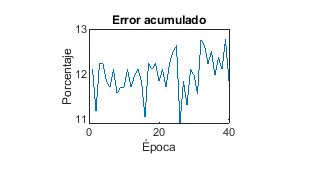

plot(1:epoca, errores);
title("Error acumulado");
ylabel("Porcentaje");
xlabel("Época");

## Validación

Este apartado no cambia en sí, pero, claro, puede ser modificado y mejorado.

num_imagenes = 15;
fallidos = 0;

for j = 1:num_imagenes % Recorre las imágenes
    for i = 1:length(categorias) % Recorre las categorías
        % Seleccionamos la imagen y la hacemos vector
        name = strcat("./validation/", categorias(i), num2str(j), ".jpg");
        p = double(reshape(imread(name), [entrada, 1]));
        salida = p;
        
        % Propagación hacia adelante
        for k = 1:num_capas
                salida = capas{k}(pesos{k} * salida + bias{k});
        end
        
        % Calculamos el error
        salida(salida>0.5) = 1;
        salida(salida<=0.5) = 0;
        salidas{k+1} = salida;
        
        error = etiquetas{i} - salida;
        
        if ~isequal(error, zeros(neuronas(end), 1))
            fallidos = fallidos + 1;
        end
    end
end

error_acumulado = 100 * fallidos / (num_imagenes * length(categorias));

fprintf("Los hiperparámetros son:");

Los hiperparámetros son:

fprintf("\tTasa de aprendizaje alfa: %f", alfa);

	Tasa de aprendizaje alfa: 0.000750

fprintf("\tNúmero de capas: %d", num_capas);

	Número de capas: 2

fprintf("\tNúmero de neuronas: " + num2str(neuronas));

	Número de neuronas: 5  2


fprintf("\nLos resultados del modelo son:");


Los resultados del modelo son:

fprintf("\tError acumulado: %f", error_acumulado);

	Error acumulado: 53.333333

fprintf("\tCasos totales: %d", num_imagenes * length(categorias));

	Casos totales: 60

fprintf("\tCasos fallidos: %d", fallidos);

	Casos fallidos: 32

## Prueba

El modelo dice que es: shine
./testing/cloudy47.jpg


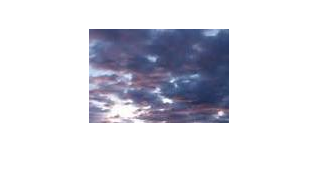

% Seleccionamos una imagen al azar
maximos = [95, 10, 48, 152];
categoria = randi(length(categorias), [1, 1]);
j = randi(maximos(categoria), [1, 1]);
name = strcat("./testing/", categorias(categoria), num2str(j), ".jpg");
p = imread(name);
salida = double(reshape(p, [entrada, 1]));

% Propagación hacia adelante
for k = 1:num_capas
    salida = capas{k}(pesos{k} * salida + bias{k});
end
salida(salida > 0.5) = 1;
salida(salida <= 0.5) = 0;

% Revisamos la salida
for i = 1:length(categorias)
    if isequal(etiquetas{i}, salida)
        res = categorias(i);
        break;
    end
end

fprintf("El modelo dice que es: %s\n", res); disp(name); imshow(p);